# 案例：压缩因子粒子群算法实现指数拟合

clear;clc;
t = 0.2*(1:3000)';
data = 400*exp(-t/5) + 10*randn(size(t));
tic;
p = PSO_ExpFit(t, data)

p =   392.6746    5.1174    0.0948


toc;

历时 1.280343 秒。


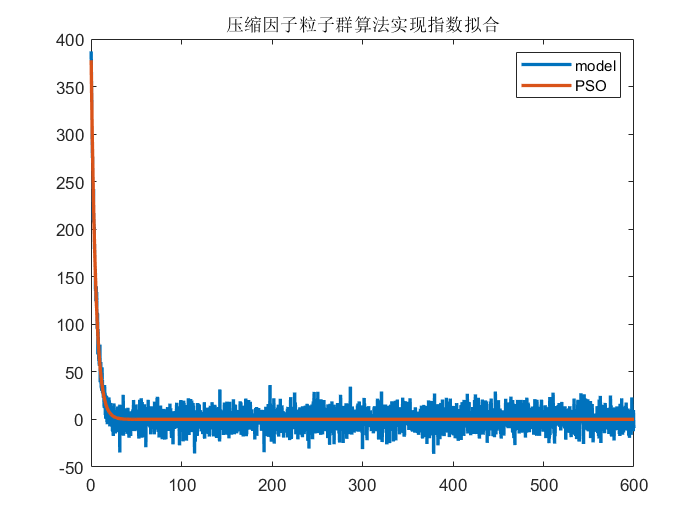

fit = p(1)*exp(-t/p(2)) + p(3);
plot(t, data, t, fit, 'LineWidth', 2)
legend('model', 'PSO');
title('压缩因子粒子群算法实现指数拟合');

function [x_opt, y_opt] = PSO_ExpFit(t, Et)
%{
函数功能：压缩因子粒子群算法实现指数拟合：y = a*exp(-x/b) + c
输入：
  t：自变量；
  Et：因变量；
输出：
  x_opt：最优解；
  y_opt：适应度（目标函数值）；
%} 
% 初始值
D = 3;                % 粒子维度，未知数个数；
IterMax = 200;        % 最大迭代次数；
Vmin = -1;            % 速度最小值；
Vmax = 1;             % 速度最大值；
c1 = 2.05;            % 学习因子1，认知部分；
c2 = 2.05;            % 学习因子2，社会部分；
N = 200;              % 种群个数；
max_sig = max(Et);
Xmin = [0.5*max_sig, -2, 0];    % 下限
Xmax = [1.5*max_sig, 4, 0.5*max_sig];  % 上限；
% 计算
phy = c1 + c2;
lamda = 2 / abs(2 - phy - sqrt(phy^2 - 4*phy));   % 压缩因子
% 初始化种群个体（限定位置和速度） 
x = rand(N, D).*repmat(Xmax - Xmin, N, 1) + repmat(Xmin, N, 1);
v = rand(N, D)*(Vmax - Vmin) + Vmin;
% 初始化个体最优位置和最优值 
p = x;
pbest = ones(1, N);
for i = 1 : N
   pbest(i) = Obj_Fit(x(i, :), t ,Et);
end
% 初始化全局最优位置和最优值 
g = ones(1, D);
gbest = inf;
for i = 1 : N
   if pbest(i) < gbest
      g = p(i, :);
      gbest = pbest(i);
   end
end
% 迭代直到满足精度或者迭代次数 
fx = zeros(1, N);
y_opt = zeros(1, IterMax);
for i = 1 : IterMax
   for j = 1 : N
      % 更新个体最优位置和最优值 
      fx(j) = Obj_Fit(x(j, :), t ,Et);
      if fx(j) < pbest(j)
         p(j, :) = x(j, :);
         pbest(j) = fx(j);
      end
      % 更新全局最优位置和最优值 
      if pbest(j) < gbest
         g = p(j, :);
         gbest = pbest(j);
      end
      % 更新位置和速度值  
      v(j, :) = lamda*v(j, :) + c1*rand*(p(j, :) - x(j, :)) + c2*rand*(g - x(j, :));
      x(j, :) = x(j, :) + v(j, :);
      % 边界条件处理 
      for ii = 1 : D
         if (v(j, ii) > Vmax) || (v(j, ii) < Vmin)
            v(j, ii) = rand*(Vmax - Vmin) + Vmin;
         end
         if (x(j, ii) > Xmax(ii)) || (x(j, ii) < Xmin(ii))
            x(j, ii) = rand*(Xmax(ii) - Xmin(ii)) + Xmin(ii);
         end
      end
   end
end
x_opt = g;
x_opt(2) = 10^(x_opt(2));
end

% 目标函数
function fitError = Obj_Fit(p0, t ,Et)
A = p0(1);
B = p0(2);
C = p0(3);
f = A*exp(-t/10^B)  + C;  
fitError = norm(Et - f);
end